simulink_signals = out.logsout

simulink_signals = Simulink.SimulationData.Dataset 'logsout' with 7 elements

                         Name        BlockPath                                
                         __________  ________________________________________ 
    1  [1x1 Signal]      u           ClosedLoopSystem_PID/Model              
    2  [1x1 Signal]      sensor      ClosedLoopSystem_PID/Mux                
    3  [1x1 Signal]      current     .../DC Motor model/PS-Simulink Converter
    4  [1x1 Signal]      arm_torque  ...Physical Model/PS-Simulink Converter3
    5  [1x1 Signal]      theta       ClosedLoopSystem_PID/log_sensor/Selector
    6  [1x1 Signal]      phi         ...edLoopSystem_PID/log_sensor/Selector1
    7  [1x1 Signal]      ref_phi     ...pSystem_PID/Model|PID_controller/Sum1

  - Use braces { 

% Time
time_1 = out.logsout{1}.Values.Time;
time_2 = out.logsout{2}.Values.Time;
% Data
u = out.logsout{1}.Values.Data;
angle_1 = out.logsout{2}.Values.Data(:,1);
angle_2 = out.logsout{2}.Values.Data(:,2);
omega_1 = out.logsout{2}.Values.Data(:,3);
omega_2 = out.logsout{2}.Values.Data(:,4);
arm_torque = out.logsout{3}.Values.Data;
theta = out.logsout{4}.Values.Data;
phi = out.logsout{5}.Values.Data;
ref_phi = out.logsout{7}.Values.Data;
ref_phi = out.logsout{6}.Values.Data;

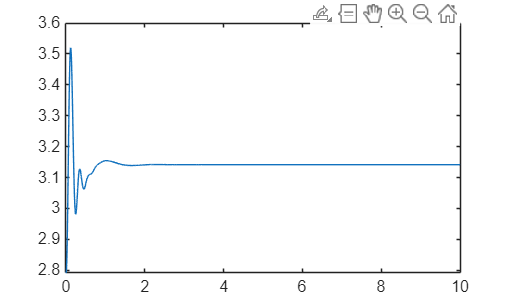

figure(1);
plot(time_1, u)
plot(time_2, sensor_1)
plot(time_2, sensor_2)

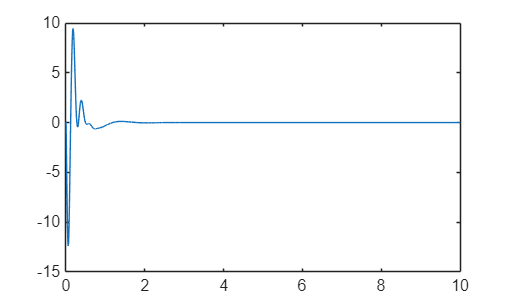

plot(time_2, sensor_3)

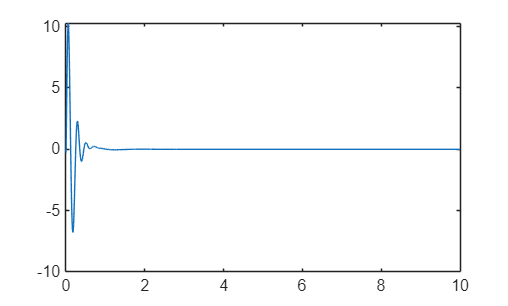

plot(time_2, sensor_4)

diff(time_2)

ans =     0.0000
    0.0003
    0.0000
    0.0015
    0.0015
    0.0017
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001


python_code = ["from rl_qube.simulink.qube3_block import start, step, stop, step_1"];

pyrun(python_code)